# Using LBP Features to Differentiate Images by Texture

Read images that contain different textures.

 kapha1= imread('Tongue - murali a.jpeg');
kapha=rgb2gray(kapha1)

kapha = 256×256 uint8 matrix
   76   83   84   76   70   69   67   61   58   56   54   50   41   32   29   31   28   29   29   29   30   30   31   31   30   30   29   29   29   29   30   30   31   31   31   31   31   32   33   34   36   36   36   37   38   39   41   41   40   39
   77   78   74   67   63   63   63   62   54   50   46   44   38   32   32   35   29   29   29   30   30   30   31   31   30   30   29   29   29   29   30   30   31   31   31   32   32   33   33   33   36   36   36   37   37   39   40   41   41   40
   81   75   70   68   65   61   60   61   50   44   38   36   34   31   31   33   29   29   30   30   30   30   31   31   31   30   30   29   29   30   30   31   30   31   32   33   34   34   33   33   36   36   36   36   37   38   39   40   42   41
   79   72   69   73   71   60   52   51   46   39   33   32   32   29   27   28   30   30   30   30   30   30   31   31   31   31   30   30   30   30   31   31   30   31   33   35   35   35   34   33   37   37   36   

 pita1= imread('image - kirti kashyap.jpg');
 pita=rgb2gray(pita1)

pita = 256×256 uint8 matrix
    97    98   100   102   102   100    98    96    99    96    95    98   103   105   103   100   104   101    99    99   101   103   103   102   102   103   104   104   104   105   106   107   104   104   104   105   108   110   110   109   112   112   111   110   109   108   107   107   107   108
    95    96    97    98    99    99    99    98    98    96    96    97   100   100    99    96   103   101    99    99   101   101   100    99   101   102   102   102   101   101   101   102   101   101   101   103   105   107   107   106   110   109   107   106   105   105   106   107   106   106
    98    97    96    94    93    93    93    94    94    95    96    98   100   101   102   103   102   101   100   101   102   102   100    99   104   103   103   102   101   100   100   100    97    97    97    99   101   103   103   102   107   105   103   102   102   103   104   105   107   107
    91    89    87    85    84    85    87    88    92    93    95   

vata1= imread('PXL_20211227_100311186 - Madhav Chauhan.jpg');
vata =rgb2gray(vata1)

vata = 256×256 uint8 matrix
   100    96   105   104    88    87    95    92    91   102   115   123   127   125   117   108   104   102    99    97    94    89    84    80    74    80    85    82    74    70    72    76    73    72    68    64    65    67    66    62    67    71    76    78    78    79    82    86    92    87
    91    94   101   102    93    92    97    98    98   106   115   118   120   119   113   107   102    99    95    91    88    85    81    79    75    77    78    77    74    73    73    75    75    65    59    62    66    66    68    72    71    74    77    78    77    79    83    87    85    83
    85    95    99    99   100    98    99   106   106   112   115   113   112   112   110   107   101    97    92    87    85    82    80    79    75    74    73    73    74    74    74    74    74    60    55    66    72    68    68    75    76    77    78    78    79    81    85    88    84    83
    90   103   101    99   105   101    98   110   110   114   116   

Display the images.

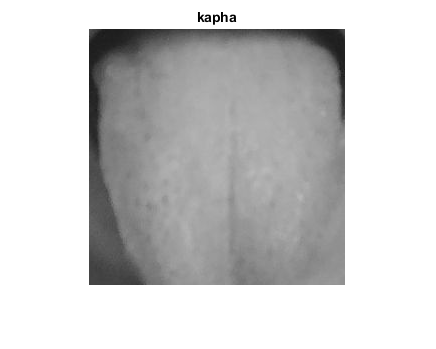

figure
imshow(kapha)
title('kapha')

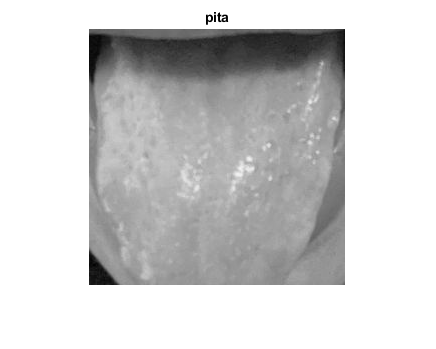


figure
imshow(pita)
title('pita')

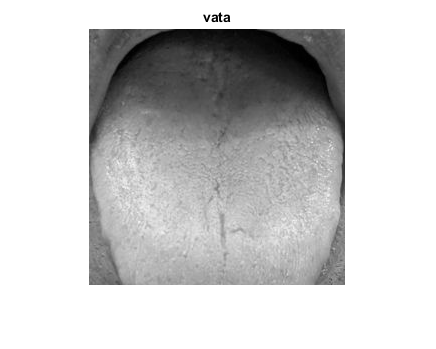


figure
imshow(vata)
title('vata')

Extract LBP features from the images to encode their texture information.

lbpkapha = extractLBPFeatures(kapha,'Upright',false);
lbppita = extractLBPFeatures(pita,'Upright',false);
lbpvata = extractLBPFeatures(vata,'Upright',false);

Gauge the similarity between the LBP features by computing the squared error between them.

kaphaVspita = (lbpkapha - lbppita).^2;
kaphaVsvata = (lbpkapha - lbpvata).^2;

Visualize the squared error to compare bricks versus bricks and bricks versus carpet. The squared error is smaller when images have similar texture.

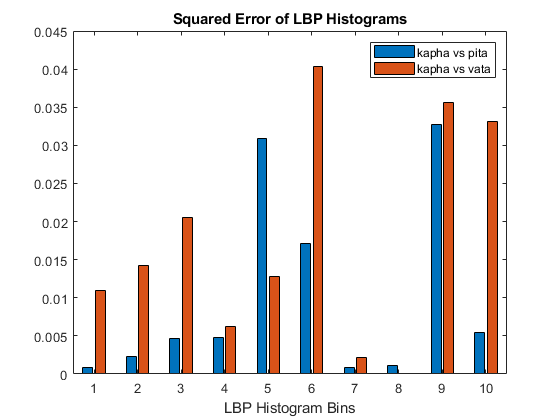

figure
bar([kaphaVspita; kaphaVsvata]','grouped')
title('Squared Error of LBP Histograms')
xlabel('LBP Histogram Bins')
legend('kapha vs pita','kapha vs vata')

*Copyright 2015 The MathWorks, Inc.*